## Decision Tree Demo 

by AhmetSacan

file = bmes.downloadurl('http://sacan.biomed.drexel.edu/lib/exe/fetch.php?rev=&media=course:ml:d3:d3demo:weightgaindata.mat');
load(file);
XT=table2array(weightgaindata);
X=XT(:,1:end-1); T=XT(:,end);
T=T>=0;
N=size(X,1);
attributes = weightgaindata.Properties.VariableNames(1:end-1);

Icross = crossvalind('kfold',N,4);
Itest = Icross==1;
Xtrain = X(~Itest,:); Ttrain=T(~Itest,:);
Xtest = X(Itest,:); Ttest=T(Itest,:);

## Train a classification tree

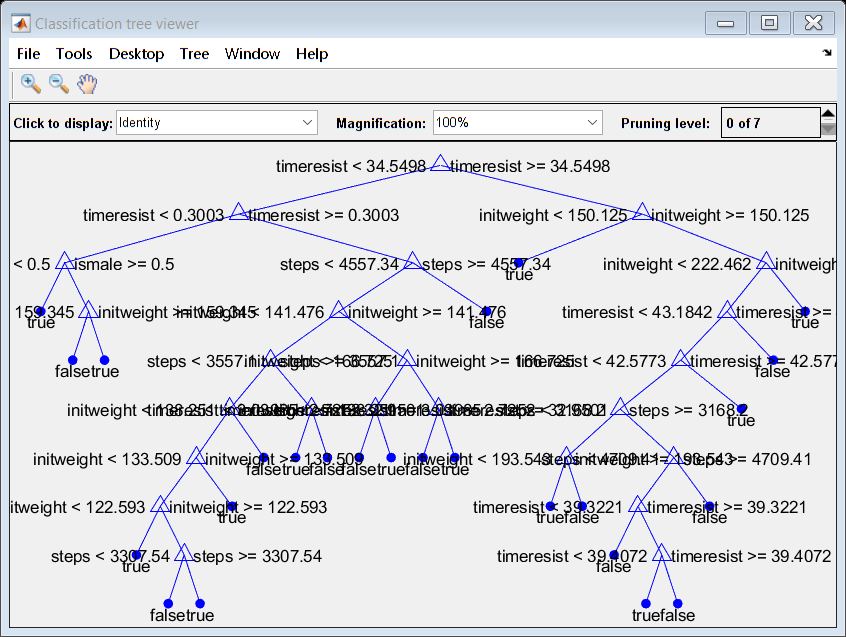

tree=fitctree(Xtrain,Ttrain, 'PredictorNames',attributes);
view(tree,'mode','graph'); %graphical view

view(tree) %rules view

Decision tree for classification
 1  if timeresist<34.5498 then node 2 elseif timeresist>=34.5498 then node 3 else true
 2  if timeresist<0.3003 then node 4 elseif timeresist>=0.3003 then node 5 else true
 3  if initweight<150.125 then node 6 elseif initweight>=150.125 then node 7 else false
 4  if ismale<0.5 then node 8 elseif ismale>=0.5 then node 9 else true
 5  if steps<4557.34 then node 10 elseif steps>=4557.34 then node 11 else true
 6  class = true
 7  if initweight<222.462 then node 12 elseif initweight>=222.462 then node 13 else false
 8  class = true
 9  if initweight<159.345 then node 14 elseif initweight>=159.345 then node 15 else true
10  if initweight<141.476 then node 16 elseif initweight>=141.476 then node 17 else true
11  class = false
12  if timeresist<43.1842 then node 18 elseif timeresist>=43.1842 then node 19 else false
13  class = true
14  class = false
15  class = true
16  if steps<3557.1 then node 20 elseif steps>=3557.1 then node 21 else false
17  if initweight

## Apply the tree to new samples and make predictions.

Ytest = tree.predict(Xtest);
perf = classperf(Ttest, Ytest);
fprintf('Accuracy of the D3 on the test set is: %g\n',perf.CorrectRate);

Accuracy of the D3 on the test set is: 0.730159


## Post-pruning the tree

tree=fitctree(Xtrain,Ttrain, 'PredictorNames',attributes);
fprintf('--- Before pruning, tree has %d nodes (%d internal nodes)\n',tree.NumNodes,sum(tree.IsBranchNode));

--- Before pruning, tree has 49 nodes (24 internal nodes)


% You can  prune based on alpha value, level, or number of nodes.
% For each pruning type, you may want to adjust alpha to optimize performance on a validation/test set.
%tree=tree.prune('alpha',0.2); 
%tree=tree.prune('nodes',5); 
tree=tree.prune('level',2); %how many levels to prune from the bottom.
fprintf('--- After  pruning, tree has %d nodes (%d internal nodes)\n',tree.NumNodes,sum(tree.IsBranchNode));

--- After  pruning, tree has 11 nodes (5 internal nodes)


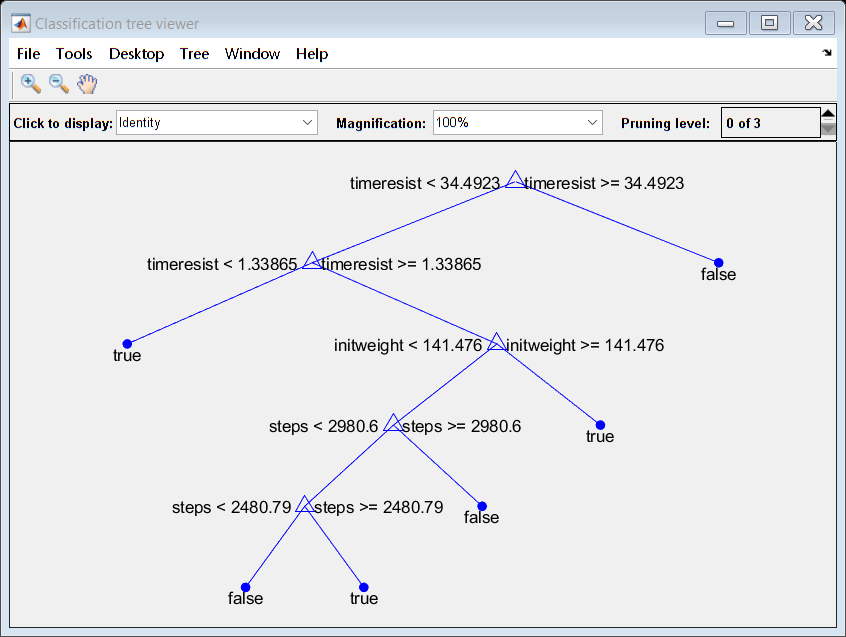

view(tree,'mode','graph')

view(tree)

Decision tree for classification
 1  if timeresist<34.4923 then node 2 elseif timeresist>=34.4923 then node 3 else false
 2  if timeresist<1.33865 then node 4 elseif timeresist>=1.33865 then node 5 else true
 3  class = false
 4  class = true
 5  if initweight<141.476 then node 6 elseif initweight>=141.476 then node 7 else true
 6  if steps<2980.6 then node 8 elseif steps>=2980.6 then node 9 else false
 7  class = true
 8  if steps<2480.79 then node 10 elseif steps>=2480.79 then node 11 else true
 9  class = false
10  class = false
11  class = true



Ytest = tree.predict(Xtest);
perf = classperf(Ttest, Ytest);
fprintf('Accuracy of the [[pruned]] D3 on the test set is: %g\n',perf.CorrectRate);

Accuracy of the [[pruned]] D3 on the test set is: 0.730159


## Limiting the tree growth during tree construction

You can also prune during tree construction, which is more efficient to calculate once; you would need to reconstruct the tree if you wanted to change a pruning parameter.

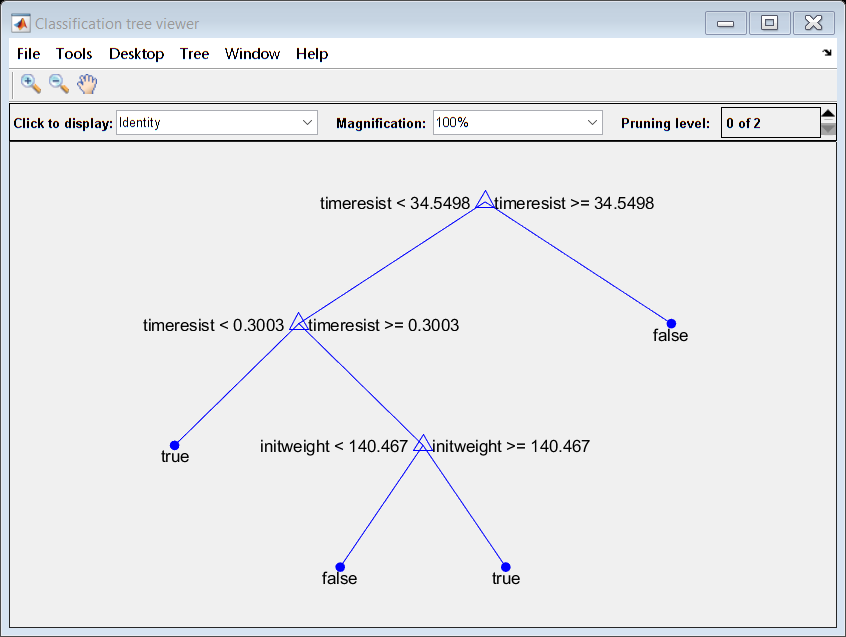

tree=fitctree(Xtrain,Ttrain, 'PredictorNames',attributes, 'MinLeafSize',40);
view(tree,'mode','graph')

view(tree)

Decision tree for classification
1  if timeresist<34.5498 then node 2 elseif timeresist>=34.5498 then node 3 else true
2  if timeresist<0.3003 then node 4 elseif timeresist>=0.3003 then node 5 else true
3  class = false
4  class = true
5  if initweight<140.467 then node 6 elseif initweight>=140.467 then node 7 else true
6  class = false
7  class = true



Ytest = tree.predict(Xtest);
perf = classperf(Ttest, Ytest);
fprintf('Accuracy of the [[pruned]] D3 on the test set is: %g\n',perf.CorrectRate);

Accuracy of the [[pruned]] D3 on the test set is: 0.758065
